# Fit of baseline and phase corrected data EDMR-on-chip

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Start of expansion to every spectrum

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
xRaw = cw.x; yRaw = cw.y;
[~, ncw] = size(xRaw);

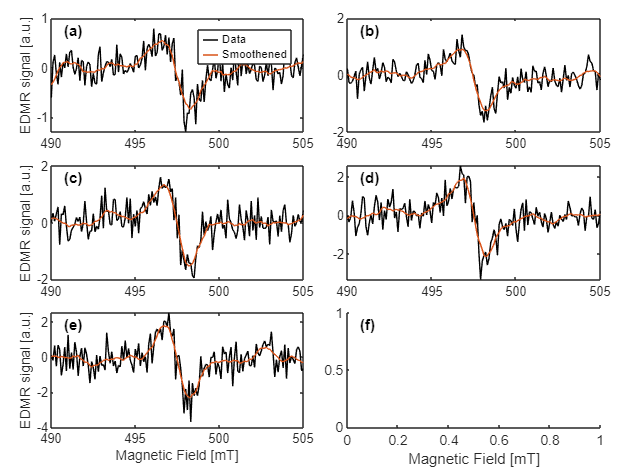

nm = 12; % Number of m parameters for datasmooth
mArray = (12 - nm/2):(12 + nm/2);
yS = repmat( ...
    {repmat(yRaw(:, 1), [1, nm])}, ...
    [1, ncw]);
% [dPay, Pay] = deal(zeros(nm, 1)); payFun = @(yS, yRaw) sum((yS -
% yRaw).^2)/numel(yS);+
for icw = 1:ncw
    xRaw_ = xRaw(:, icw);
    yRaw_ = yRaw(:, icw);
    figure('Visible', 'off')
    plot(xRaw_, yRaw_, 'DisplayName', 'raw')
    hold on
    for im = 1:nm
        yS{icw}(:, im) = datasmooth(yRaw_, mArray(im), 'savgol');
        plot(xRaw_, yS{icw}(:, im), 'DisplayName', sprintf('%i', mArray(im)))
%         Pay(im) = payFun(yS{icw}(:, im), yRaw_);
%         if im > 1
%             dPay(im) = Pay(im) - Pay(im - 1);
%         end
    end
    legend
end
M_PARAMS = 10;
y = datasmooth(yRaw, M_PARAMS, 'savgol');
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    plot(xRaw(:, icw), yRaw(:, icw), 'Color', 'black')
    hold on
    plot(xRaw(:, icw), y(:, icw));
end
lgd = legendFirstTile(tL, {'Data', 'Smoothened'});
annotateSubplotId(tL)
labelAxesFig(tL, 'Magnetic Field [mT]', 'EDMR signal [a.u.]')

#### Spin systems

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [1 1.3], ...
    Nucs = 'Si', A = [151 269], ...
    FieldOffset = -1.2);
VaryDb = struct( ...
    lw = SysDb.lw, ...
    FieldOffset = 2);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [1. 0.55], ...
    weight = 0.3);
VaryV = struct( ...
    lw = SysV.lw, ...
    weight = SysV.weight);

Exp.mwFreq = 14; % GHz
Exp.nPoints = numel(xRaw_);

% Sys = {SysDb, SysV};
% Vary = {VaryDb, VaryV};

## Field offset for fit with two spin systems

*pepperFieldOffset *does not work with more than 1 spin system. Correction is done shifting the magnetic field array, then the shift is checked again after the fitting.

Since we noticed that one spin system fits the data well, below I fit with *peppeFieldOffset* directly and then correct the data after the fit.

% BOffset = [1.4, 1.3, 1.25, 1.25];
% % figure()
% % tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact')
% x = xRaw;
% for icw = 1:ncw
%     % nexttile
%     figure('Visible', 'off')
%     x(:, icw) = xRaw(:, icw) + BOffset(icw);
%     x_ = x(:, icw); y_ = y(:, icw); xRaw_ = xRaw(:, icw);
%     Exp.Range = [min(xRaw_) max(xRaw_)];
%     plot(x_, y_);
%     hold on
%     plot(xRaw_, scaleY(pepper(Sys, Exp), y_), 'Color', [0 0 0])
% end

% Sys = SysDb;
% Vary = VaryDb;
% 
% icw = 2;
% x_ = x(:, icw); y_ = y(:, icw);
% Exp.Range = [min(x_) max(x_)];
% Exp.mwFreq = 14;
% esfit(y_, @pepper, {Sys, Exp}, {Vary});

Sys = SysDb;
Vary = VaryDb;

x = xRaw;
wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');
for icw = 1:ncw
    xRaw_ = xRaw(:, icw); y_ = y(:, icw);
    Exp.Range = [min(xRaw_) max(xRaw_)];
    Exp.mwFreq = 14;
    Fit_ = esfit(y_, @pepperFieldOffset, {Sys, Exp}, {Vary});
    if icw == 1
        Fit = repmat(Fit_, 1, ncw);
    else
        Fit(icw) = Fit_;
    end
    % Update B with the best value of Field Offset
    x(:, icw) = xRaw(:, icw) - Fit(icw).pfit(2);
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [151, 1]
Model function name:      pepperFieldOffset
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 9.70958e-02   edge 1.00000e-01   initial simplex
iteration   2: value 9.32110e-02   edge 2.00000e-01   contraction outside
iteration   3: value 8.93234e-02   edge 2.60000e-01   reflection
iteration   4: value 8.66237e-02   edge 1.62500e-01   contraction inside
iteration   5: value 8.62973e-02   edge 2.60000e-01   reflection
iteration   6: value 8.57439e-02   edge 1.46250e-01   contraction inside
iteration   7: value 8.54477e-02   edge 1.58438e-01   contraction inside
iteration   8: value 8.53952e-02   edge 9.03906e-02   contraction inside
iteration   9: value 8.52972e-02   edge 

delete(wbar)

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    cwStruct = cw.cwStruct;
    save([Opt.SFolder, '\fit_chip'], 'x', 'y', 'cwStruct', 'Fit');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end

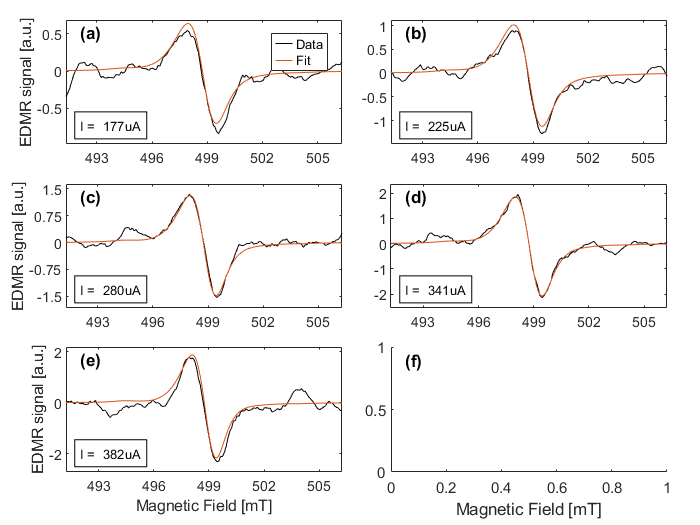

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    x_ = x(:, icw); y_ = y(:, icw); yFit_ = Fit(icw).fit;
    h(1) = plot(x_, y_, 'Color', 'black');
    hold on
    h(2) = plot(x_, yFit_);

    xticks(493:3:508);
    xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end
nexttile(2); yticks(-1:.5:1);
nexttile(3); yticks(-1.5:.75:1.5);
nexttile(4); yticks(-2:1:2);
annotateSubplotId(tL)
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")
lgd = legendFirstTile(tL, {'Data', 'Fit'}, h);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, "fit chip", "pdf", 'fit')

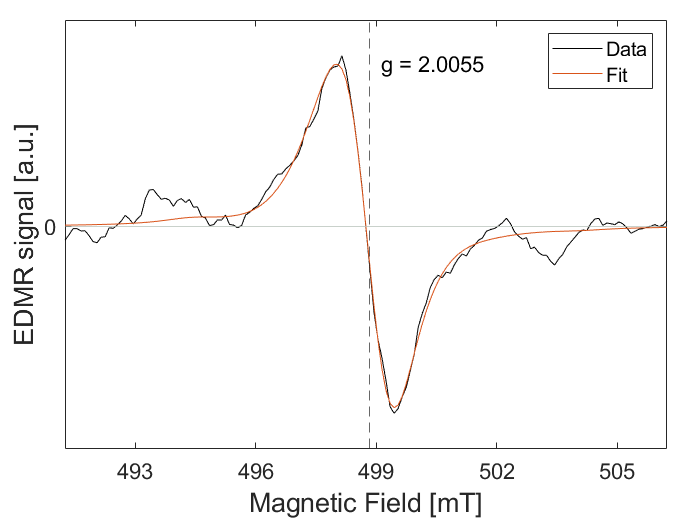

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = "D:\Profile\qse\Files\_EDMRoC pinSC\Images";

load([Opt.LFolder, '\fit_chip']);

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
icw = 4; % Vbias = 1.5 V
grayC = '#b2beb5';
x_ = x(:, icw); y_ = y(:, icw); yFit_ = Fit(icw).fit;
ax = nexttile(1);
h(1) = plot(x_, y_, Color = 'black', DisplayName = 'Data');
hold on
h(2) = plot(x_, yFit_, DisplayName = 'Fit');

h(3) = xline(mhz2mt(14*1000, 2.0052), '--');
h(4) = yline(0, 'Color', grayC);

xticks(493:3:508); yticks(0);
xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

Label3 = "g = 2.0055";
text(0.525, 0.9, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")
legend([h(1) h(2)])
exportFig(gcf, Opt.SFolder, "_fit chip final", "pdf");
exportFig(gcf, Opt.SFolder, "_fit chip final", "png");

figure()
plot(x, y, x, scaleY(cumtrapz(y), y))
[~, id] = max(cumtrapz(y))
xline(x(id))
hold on
xnew = x(id:end);
ynew = cumtrapz(y(1:id));
ynewnew = flip(ynew);

plot(xnew, scaleY(ynewnew, y))

Exp.Range = [min(x) max(x)];
Sys = SysDb;
Vary = VaryDb;
Fit1comp = esfit(y, @pepper, {Sys, Exp}, {Vary});

## ppAmp vs Vbias

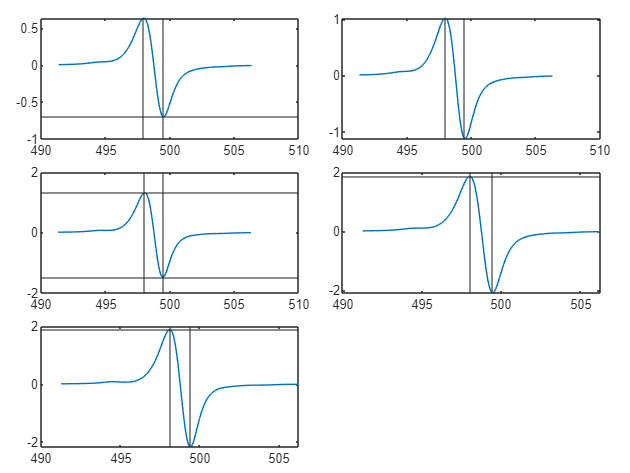

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_chip']);
[~, ncw] = size(x);

[ppAmp, yMax, yMin, xMax, xMin] = deal(zeros(1, ncw));

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    yFit_ = Fit(icw).fit;
    [ppAmp(icw), yMax(icw), yMin(icw), xMax(icw), xMin(icw)] = getPeakToPeakAmp(x_, yFit_);
    
    nexttile
    plot(x_, yFit_)
    hold on
    yline(yMax(icw)); yline(yMin(icw));
    xline(xMax(icw)); xline(xMin(icw));
end

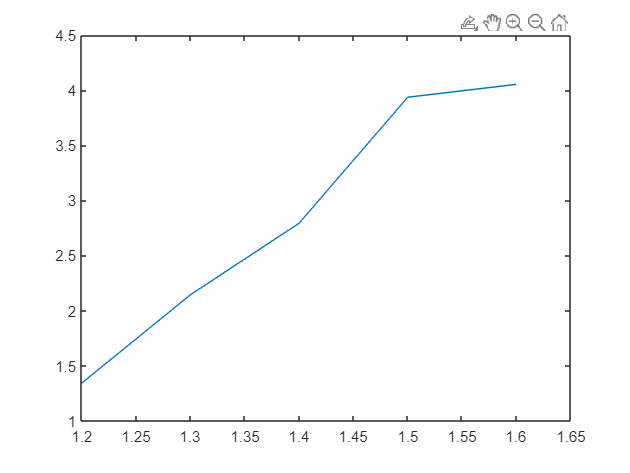

figure()
plot([1.2, 1.3, 1.4, 1.5, 1.6], ppAmp) % Last datapoint will be omitted

## Figure amplitude pp vs Vbias

Expected linear behavior.

Last datapoint (Vbias = 1.6 V) is taken out.

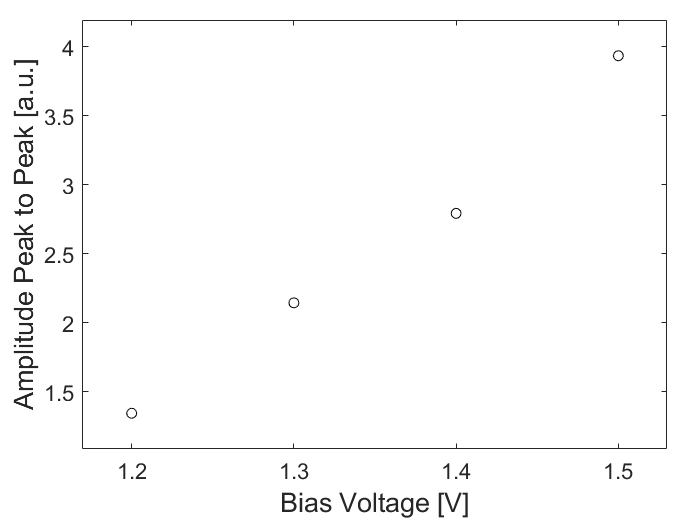

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');

ax = nexttile(1);
Vbias = 1.2:0.1:1.5; ppAmpCut = ppAmp(1:end - 1);
h(1) = plot(Vbias, ppAmpCut, 'o', 'Color', 'black');


xticks(Vbias); 
xlim(setAxLim(Vbias, 0.1)); ylim(setAxLim(ppAmpCut, 0.1));

labelAxesFig(tL, "Bias Voltage [V]", "Amplitude Peak to Peak [a.u.]")
exportFig(gcf, Opt.SFolder, "_ppAmp", "pdf");
exportFig(gcf, Opt.SFolder, "_ppAmp", "png");